# Reading Data from the Arduino

(updated 1/17/23)

This script shows how to read data from an Arduino over serial and save it in a usable way. 

*Upload the ArduinoCommunication code to the Arduino before running.*

#### **Select your operating system. **

For a PC, the arduino port will be something like "COM6", and for a Mac, it will be something like "/dev/cu.usbmodem1451"

portType = "COM" % The text pattern to look for (OS dependent)

portType = "COM"

#### Clear previous workspace data

clear dataTable dataArray

#### Automatically find the serial port the Arduino is connected to

allPorts = serialportlist;  % Creates a list of all available serial ports

% Using the text pattern, this creates a logical array of matching ports
matchingPorts = startsWith(allPorts, portType);   

if any(matchingPorts)                   % If any matches were found,              
    numMatches = sum(matchingPorts);    % Count the number of matches.
    if size(numMatches) > 1             % If multiple matching ports were found, 
        error("Multiple ports found")   % throw an error.
    else                                % If only one match was found,
        port = allPorts(matchingPorts)% that string is the arduino port.
    end
else                                    % If no ports were found,
    error("Port not found")             % throw an error.
end

port = "COM3"

#### Create a serialport object to talk to the Arduino

ard = serialport(port, 115200);   % Creates a device object (serial port, baud rate)
configureTerminator(ard, "CR/LF") % Sets the line terminator (Carridge Return/ Line Feed)

#### Wait for the Arduino

When the Arduino is ready, it sends "Ready!"

readline(ard); % Read one line of data from the Arduino

#### Tell the Arduino to start sending data

disp('Starting Counting Event in Arduino')

Starting Counting Event in Arduino


writeline(ard,"S"); % Sends the start command to the Arduino (device, string to send)

Read data from Arduino

k = 0; % Array index

% Read the first line of output from the Arduino
newData = readline(ard);

% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished',8)) 
    k = k + 1; % k++

    % Save the new line of text to stringArray(k)
    stringArray(k,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end


#### **Disconect from the Arduino **

clear ard;

#### **Format the input data**

The data collected is just an array of strings, so in order to do anything useful, we need to convert the strings to numbers

%cell2mat(stringArray)
% Transpose stringArray
%stringArray = stringArray';

% Change the string array to a cell array using tab delimiter 
dataArray = str2double(stringArray);

% Create a new table to organize the data

In this example, we only have one data variable. To make a table with multiple variables, you could do something like this:

dataTable = array2table(dataArray,"VariableNames",{'time', 'motor', 'vel', 'pos'})

dataTable = array2table(dataArray,"VariableNames",{'pos', 'vel', 'motor', 'pos2', 'vel2', 'motor2', 'forwardv','rotationalv', 'sumV', 'differenceV', 'time'})

dataTable = 466×9 table
    pos     vel     motor    pos2    vel2    motor2    forwardv    rotationalv    time
    ____    ____    _____    ____    ____    ______    ________    ___________    ____

       0       0       0        0       0        0          0            0         14 
       0       0    3.83        0       0     3.83          0            0         19 
       0    0.39    3.83        0       0     3.83       0.05          0.1         24 
       0       0    3.83        0    0.39     3.83       0.05         -0.1         29 
    0.01    0.79    3.83     0.01    0.39     3.83       0.14          0.1         34 
    0.02    0.39    3.83     0.01    0.39     3.83       0.0


% Save data to a .mat file (in case you want to work with it later)
save stepData.mat dataTable

#### Plot the data+

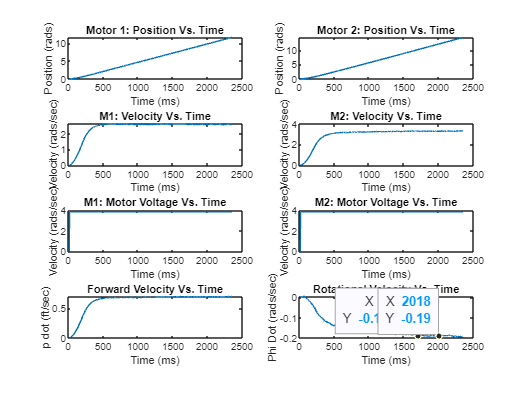

subplot(5,2,1);
plot(dataTable.time, dataTable.pos)
title('Motor 1: Position Vs. Time')
ylabel('Position (rads)')
xlabel('Time (ms)')

subplot(5,2,3);
% moving average filter
t = dataTable.time;
v = dataTable.vel;
windowSize = 40;
b = (1/windowSize) * ones(1, windowSize);
a = 1;
y = filter(b,a,v);
plot(t, y)
title('M1: Velocity Vs. Time')
ylabel('Velocity (rads/sec)')
xlabel('Time (ms)')

subplot(5,2,5);
plot(dataTable.time, dataTable.motor)
title('M1: Motor Voltage Vs. Time')
ylabel('Velocity (rads/sec)')
xlabel('Time (ms)')

subplot(5,2,2);
plot(dataTable.time, dataTable.pos2)
title('Motor 2: Position Vs. Time')
ylabel('Position (rads)')
xlabel('Time (ms)')

subplot(5,2,4);
% moving average filter
t = dataTable.time;
v2 = dataTable.vel2;
windowSize = 40;
b2 = (1/windowSize) * ones(1, windowSize);
a2 = 1;
y2 = filter(b2,a2,v2);
plot(t, y2)
title('M2: Velocity Vs. Time')
ylabel('Velocity (rads/sec)')
xlabel('Time (ms)')

subplot(5,2,6);
plot(dataTable.time, dataTable.motor2)
title('M2: Motor Voltage Vs. Time')
ylabel('Velocity (rads/sec)')
xlabel('Time (ms)')

subplot(5,2,7);
t = dataTable.time;
v3 = dataTable.forwardv;
windowSize = 40;
b3 = (1/windowSize) * ones(1, windowSize);
a3 = 1;
y3 = filter(b3,a3,v3);
plot(t, y3)
title('Forward Velocity Vs. Time')
ylabel('p dot (ft/sec)')
xlabel('Time (ms)')

subplot(5,2,8);
t = dataTable.time;
v4 = dataTable.rotationalv;
windowSize = 40;
b4 = (1/windowSize) * ones(1, windowSize);
a4 = 1;
y4 = filter(b4,a4,v4);
plot(t, y4)
title('Rotational Velocity Vs. Time')
ylabel('Phi Dot (rads/sec)')
xlabel('Time (ms)')


subplot(5,2,9);
t = dataTable.time;
v5 = dataTable.sumV;
windowSize = 40;
b5 = (1/windowSize) * ones(1, windowSize);
a5 = 1;
y5 = filter(b5,a5,v5);
plot(t, y5)
title('SumV Vs. Time')
ylabel('Voltage (ft/sec)')
xlabel('Time (ms)')

subplot(5,2,10);
t = dataTable.time;
v6 = dataTable.differenceV;
windowSize = 40;
b6 = (1/windowSize) * ones(1, windowSize);
a6 = 1;
y6 = filter(b6,a6,v6);
plot(t, y6)
title('Difference V Vs. Time')
ylabel('Voltage (ft/sec)')
xlabel('Time (ms)')
